% Check for system plot in time
syms s t
ts = (-4.3*s+0.7525)/((s^2+2.051*s+0.3283)*s^2)

$$ts = -\frac{-\frac{301}{400}+\frac{43\,s}{10}}{s^{2}\,\left(\frac{3283}{10000}+\frac{2051\,s}{1000}+s^{2}\right)}$$

y(t) = ilaplace(ts)

$$y(t) = \frac{1075\,t}{469}+\frac{344000\,{\mathrm{e}}^{-\frac{7\,t}{40}}}{11907}-\frac{78743750\,{\mathrm{e}}^{-\frac{469\,t}{250}}}{53450523}-\frac{6030750}{219961}$$

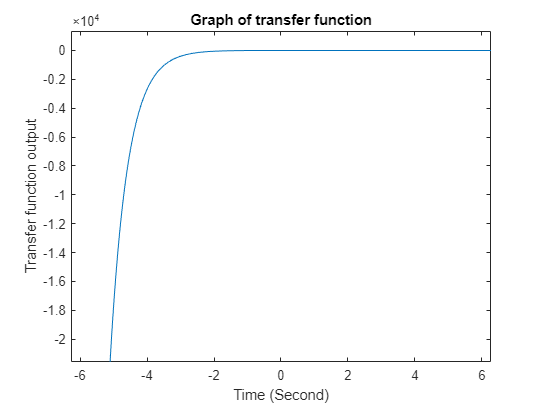

$$ts = 1+\frac{43\,\varphi }{10}+\frac{469\,d}{250}$$

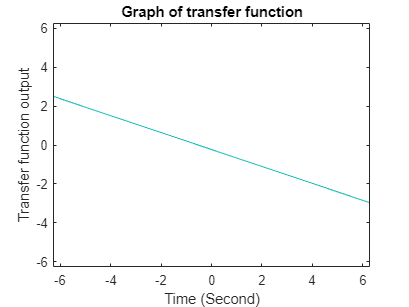

ezplot(y(t))
title("Graph of transfer function")
xlabel("Time (Second)")
ylabel("Transfer function output")

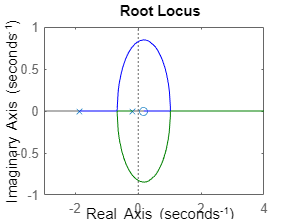

% Creat system Root locuas
sys = tf([-4.3 0.7525],[1 2.051 0.3283]);
rlocus(sys)

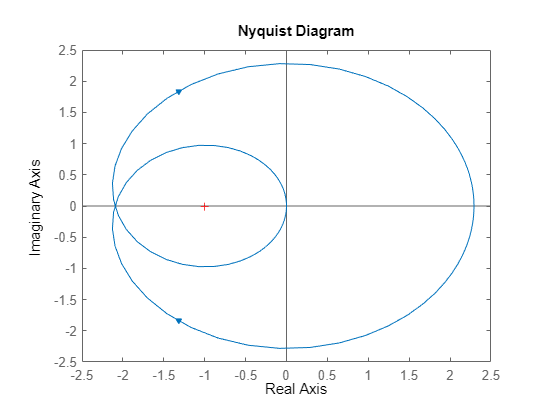

% Creat system Nyquist diagram
H = tf([-4.3 0.7525],[1 2.051 0.3283]);
nyquist(H)

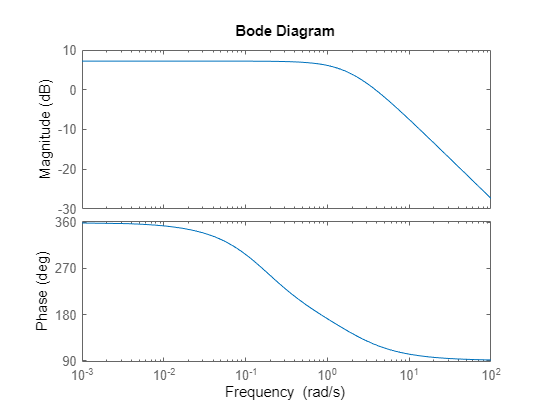

% Creat system Bode diagram
H = tf([-4.3 0.7525],[1 2.051 0.3283]);
bode(H)

syms s
Gs = (-4.3*(s-0.175))/(s^2+2.051*s+0.3283)

$$Gs = -\frac{-\frac{301}{400}+\frac{43\,s}{10}}{\frac{3283}{10000}+\frac{2051\,s}{1000}+s^{2}}$$

k = -1/Gs

$$k = \frac{\frac{3283}{10000}+\frac{2051\,s}{1000}+s^{2}}{-\frac{301}{400}+\frac{43\,s}{10}}$$

y = diff(k,s)

$$y = \frac{\frac{2051}{1000}+2\,s}{-\frac{301}{400}+\frac{43\,s}{10}}-\frac{43\,\left(\frac{3283}{10000}+\frac{2051\,s}{1000}+s^{2}\right)}{10\,{\left(-\frac{301}{400}+\frac{43\,s}{10}\right)}^{2}}$$

r = solve(y,s)

$$r = \left(\begin{array}{c} \frac{7}{40}-\frac{7\,\sqrt{586}}{200}\\ \frac{7\,\sqrt{586}}{200}+\frac{7}{40} \end{array}\right)$$

% Stability analysis
numg=[1]; deng=[1 6.351 0.5033]; sysg= tf(numg,deng);
sys=feedback(sysg,[1]);
pole(sys)

ans =    -6.1047
   -0.2463


% Creat Contorller
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



G = (-4.3*(s-0.175))/((s+1.876)*(s+0.175))

G =
 
     -4.3 s + 0.7525
  ----------------------
  s^2 + 2.051 s + 0.3283
 
Continuous-time transfer function.



sisotool(G)